11.5（L`形薄膜波动`）实时脚本

由张志涌编写、修改于 2023.1。

119201`阶稀疏矩阵``A``的前6个特征值`

m = 200;
h = 1/m;
A = delsq(numgrid('L',2*m+1))/h^2;
lambda = eigs(A,6,0);
fprintf('%.5f \n',lambda)

9.64147 
15.19694 
19.73880 
29.52033 
31.91583 
41.47510 


L`形薄膜的特征值和特征函数`

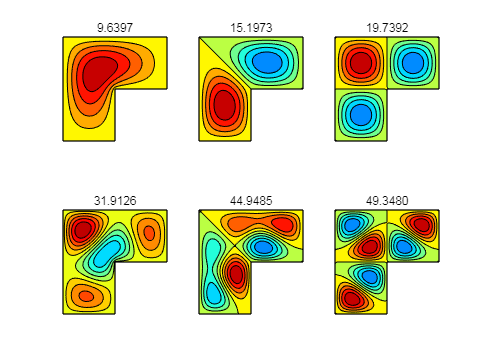

clf,set(gcf,'Color','w')
K=[1,2,3,5,7,8];%k=32;
for jj=1:6
   [L,lambda] = membranetx(K(jj));
   N=length(L);k=(N+1)/2+1;
   L(k:N,k:N)=NaN;
   subplot(2,3,jj)
   contourf(L,9)
   if jj==1;contourf(L,4);end
   colormap(jet)
   caxis([-1.7,max(L(:))])
   title(num2str(lambda,'%.4f'))
   axis equal off
   view(90,90)
   line([1,1],[1,N],[0,0],'Color','k','Linewidth',1)
   line([1,N],[1,1],[0,0],'Color','k','Linewidth',1)
   line([N,N],[1,k-1],[0,0],'Color','k','Linewidth',1)
   line([1,k-1],[N,N],[0,0],'Color','k','Linewidth',1)
   line([k-1,N],[k-1,k-1],[0,0],'Color','k','Linewidth',1)
   line([k-1,k-1],[k-1,N],[0,0],'Color','k','Linewidth',1)
end